# Homework 7  - Farshad Bolouri - R11630884

### Problem 1) 

clear
close all

### X1) real valued, normally distributed with mean mX=0 and variance σX^2=1

Using the functions rand(), randn(), or randi(), create column vectors of length 1000 filled with realizations of a random variable with the following properties:

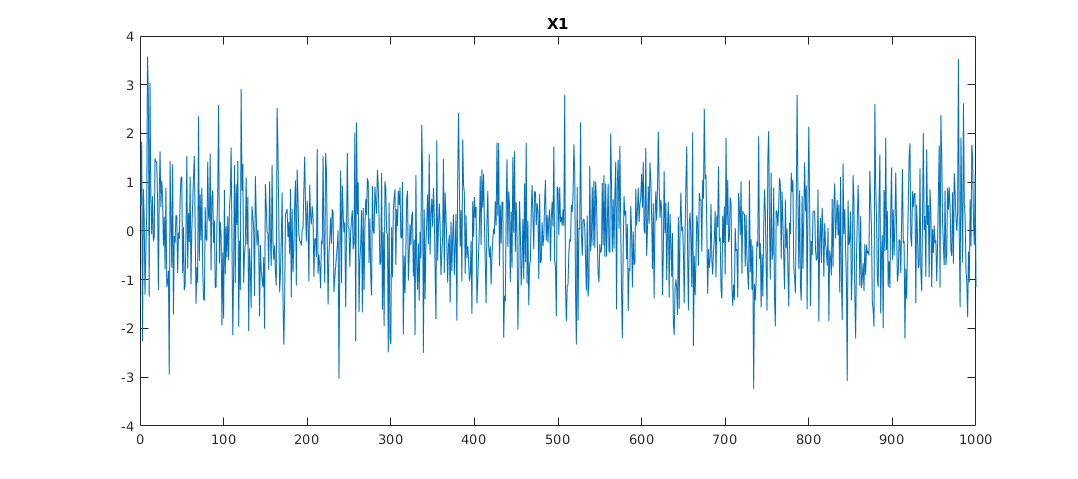

N = 1000;
X1 = randn(1, N);
graph = figure;
plot(X1)
title('X1')
set(graph,'Units','normalized','Position',[0 0 1 0.25]);

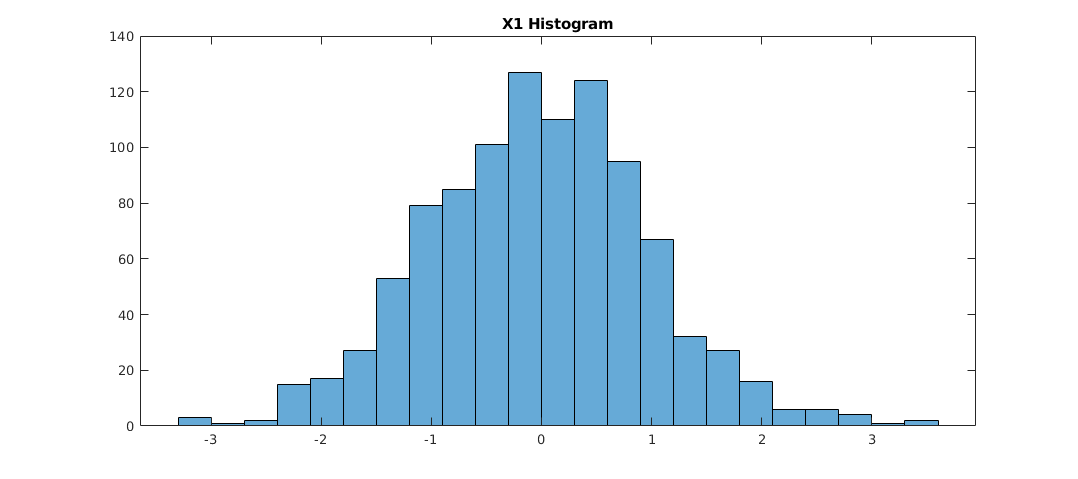

graph = figure;
histogram(X1)
title('X1 Histogram')
set(graph,'Units','normalized','Position',[0 0 1 0.25]);

*Theoretical Equations for Mean and Variance*

*Mean:*


$$\mu =\frac{1}{N}\sum_{i=1}^N x_i$$


*Variance:*


$$\sigma^2 = \frac{\displaystyle\sum_{i=1}^{N}(x_i - \mu)^2} {N - 1}
$$


% Theoretical Mean and Variance
mu1_theoretical = sum(X1)/N;
var1_theoretical = sum((X1-mu1_theoretical).^2)/(N - 1);

fprintf("Theoretical Mean of X1 = %f\n\nTheoretical Variance of X1 = %f"...
    , mu1_theoretical, var1_theoretical)

Theoretical Mean of X1 = -0.032632

Theoretical Variance of X1 = 0.997932

% MATLAB's Mean and Variance
mu1 = mean(X1);
var1 = var(X1);

fprintf("MATLAB's Mean of X1 = %f\n\nMATLAB's Variance of X1 = %f"...
    , mu1, var1);

MATLAB's Mean of X1 = -0.032632

MATLAB's Variance of X1 = 0.997932

% Percent Difference between the results
if mu1_theoretical >= mu1
    mu1_difference = 100*(mu1_theoretical - mu1)/mu1_theoretical;
    var1_difference = 100*(var1_theoretical - var1)/var1_theoretical;
else
    mu1_difference = 100*(mu1 - mu1_theoretical)/mu1;
    var1_difference = 100*(var1 - var1_theoretical)/var1;
end

fprintf("Difference between MATLAB's Mean and Theoretical Mean = %.2f%%\n\n" +...
    "Difference between MATLAB's Variance and Theoretical Variance = %.2f%%"...
    , mu1_difference, var1_difference);

Difference between MATLAB's Mean and Theoretical Mean = -0.00%

Difference between MATLAB's Variance and Theoretical Variance = 0.00%

*The results are equivalent between the Theoretical and MATLAB's calculations.*

*Looking at MATLAB's docs for 'mean' and 'var' functions it seems like they are using the same formula as the one shown before:*

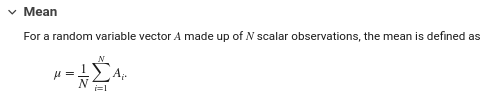

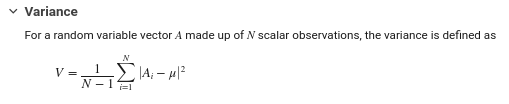

### X2) real valued, normally distributed with mean mX=5 and variance σX^2=1

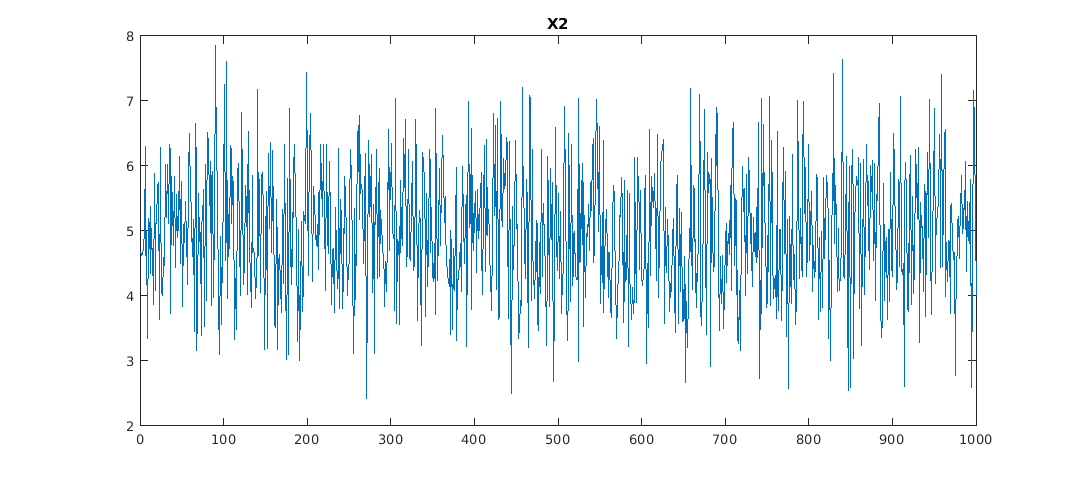

X2 = randn(1, N) + 5;
graph = figure;
plot(X2)
title('X2')
set(graph,'Units','normalized','Position',[0 0 1 0.25]);

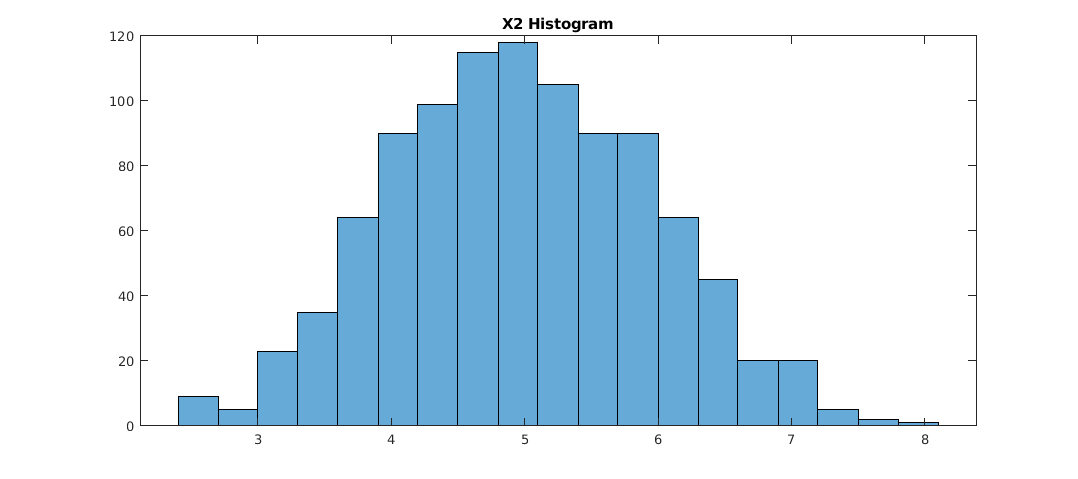

graph = figure;
histogram(X2)
title('X2 Histogram')
set(graph,'Units','normalized','Position',[0 0 1 0.25]);

% Theoretical Mean and Variance
mu2_theoretical = sum(X2)/N;
var2_theoretical = sum((X2-mu2_theoretical).^2)/(N - 1);

fprintf("Theoretical Mean of X2 = %f\n\nTheoretical Variance of X2 = %f"...
    , mu2_theoretical, var2_theoretical)

Theoretical Mean of X2 = 4.979052

Theoretical Variance of X2 = 0.945813

% MATLAB's Mean and Variance
mu2 = mean(X2);
var2 = var(X2);

fprintf("MATLAB's Mean of X2 = %f\n\nMATLAB's Variance of X2 = %f"...
    , mu2, var2);

MATLAB's Mean of X2 = 4.979052

MATLAB's Variance of X2 = 0.945813

% Percent Difference between the results
if mu2_theoretical >= mu2
    mu2_difference = 100*(mu2_theoretical - mu2)/mu2_theoretical;
    var2_difference = 100*(var2_theoretical - var2)/var2_theoretical;
else
    mu2_difference = 100*(mu2 - mu2_theoretical)/mu2;
    var2_difference = 100*(var2 - var2_theoretical)/var2;
end

fprintf("Difference between MATLAB's Mean and Theoretical Mean = %.2f%%\n\n" +...
    "Difference between MATLAB's Variance and Theoretical Variance = %.2f%%"...
    , mu2_difference, var2_difference);

Difference between MATLAB's Mean and Theoretical Mean = 0.00%

Difference between MATLAB's Variance and Theoretical Variance = 0.00%

*The results are equivalent between the Theoretical and MATLAB's calculations.*

### X3) real valued, normally distributed with mean mX=10 and variance σX^2=25

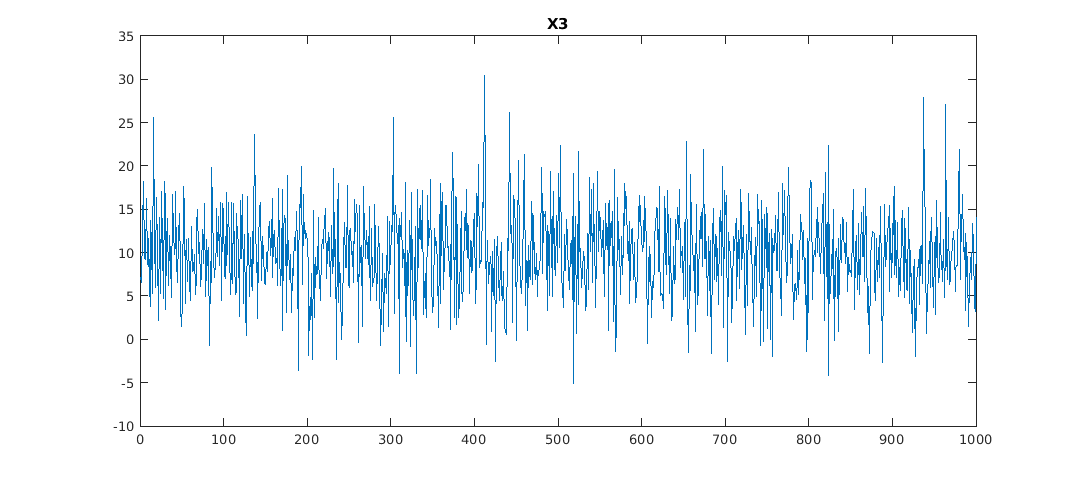

X3 = sqrt(25)*randn(1, N) + 10;
graph = figure;
plot(X3)
title('X3')
set(graph,'Units','normalized','Position',[0 0 1 0.25]);

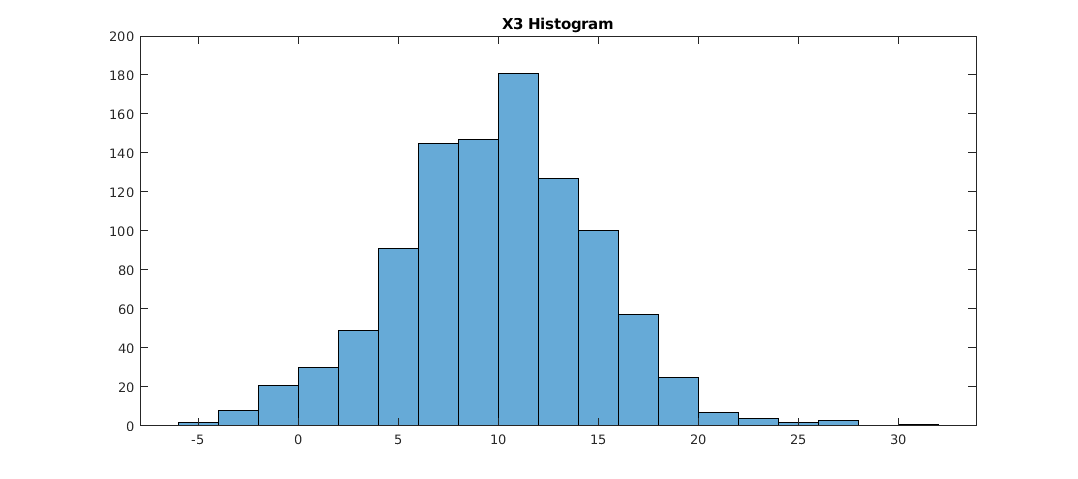

graph = figure;
histogram(X3)
title('X3 Histogram')
set(graph,'Units','normalized','Position',[0 0 1 0.25]);

% Theoretical Mean and Variance
mu3_theoretical = sum(X3)/N;
var3_theoretical = sum((X3-mu3_theoretical).^2)/(N - 1);

fprintf("Theoretical Mean of X3 = %f\n\nTheoretical Variance of X3 = %f"...
    , mu3_theoretical, var3_theoretical)

Theoretical Mean of X3 = 9.897076

Theoretical Variance of X3 = 24.814815

% MATLAB's Mean and Variance
mu3 = mean(X3);
var3 = var(X3);

fprintf("MATLAB's Mean of X3 = %f\n\nMATLAB's Variance of X3 = %f"...
    , mu3, var3);

MATLAB's Mean of X3 = 9.897076

MATLAB's Variance of X3 = 24.814815

% Percent Difference between the results
if mu3_theoretical >= mu3
    mu3_difference = 100*(mu3_theoretical - mu3)/mu3_theoretical;
    var3_difference = 100*(var3_theoretical - var3)/var3_theoretical;
else
    mu3_difference = 100*(mu3 - mu3_theoretical)/mu3;
    var3_difference = 100*(var3 - var3_theoretical)/var3;
end

fprintf("Difference between MATLAB's Mean and Theoretical Mean = %.2f%%\n\n" +...
    "Difference between MATLAB's Variance and Theoretical Variance = %.2f%%"...
    , mu3_difference, var3_difference);

Difference between MATLAB's Mean and Theoretical Mean = 0.00%

Difference between MATLAB's Variance and Theoretical Variance = 0.00%

*The results are equivalent between the Theoretical and MATLAB's calculations.*

### X7) real valued, uniformly distributed in the range of (0,1)

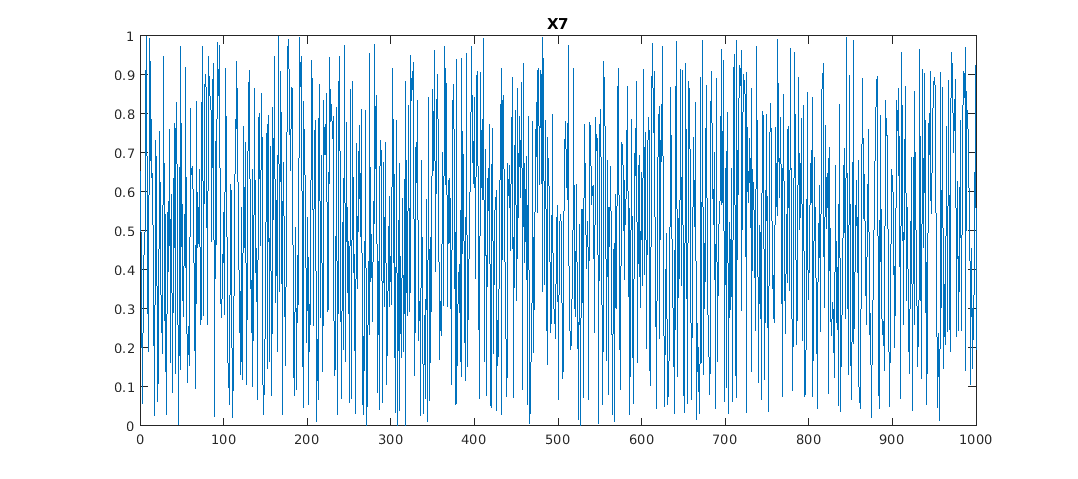

X7 = rand(1, N);
graph = figure;
plot(X7)
title('X7')
set(graph,'Units','normalized','Position',[0 0 1 0.25]);

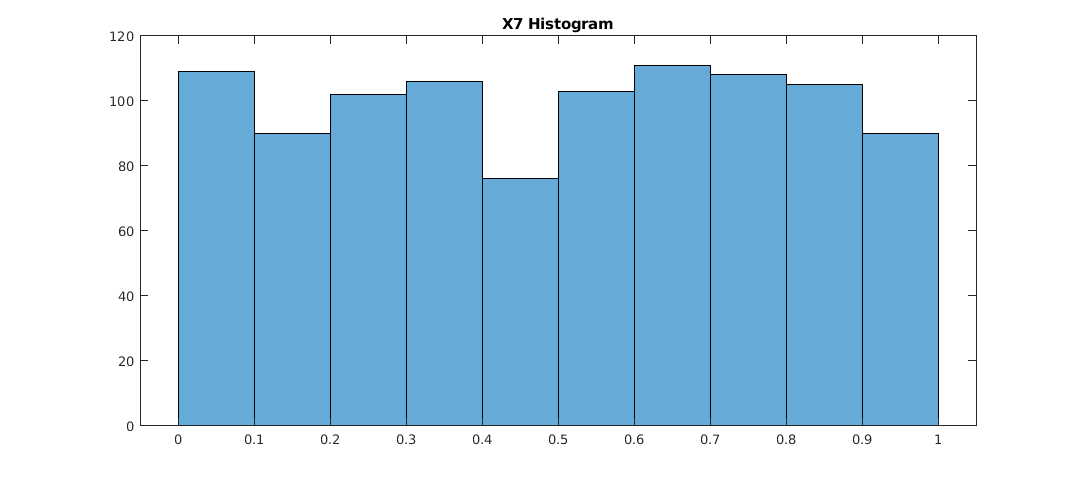

graph = figure;
histogram(X7)
title('X7 Histogram')
set(graph,'Units','normalized','Position',[0 0 1 0.25]);

Mean of a continuous random variable:


$$\mu = \mathrm{E}(X) = \sum x\,p(x),$$


Mean based on the PDF:


$$\mu = \mathrm{E}(X) = \int_{A}^{B} x\,f(x)\;dx.$$


Variance of a continuous random variable:


$$\mathrm{var}(X) = \sigma^2 = \mathrm{E}[(X - \mu)^2], \qquad\text{where } \mu = \mathrm{E}(X).$$


Variance based on the PDF:


$$\mathrm{var}(X) = \sigma^2 = \mathrm{E}[(X - \mu)^2] = \int_{A}^{B} (x-\mu)^2 f(x)\;dx.$$


PDF of Uniformly Disrtibuted random vectors:


$$f\left(x\right)=\frac{1}{B-A},\;A\le x\le B$$


*Now let's calculate the "true" mean and variance using the probability density function for X7:*


$$\begin{array}{l}
A\;=\;0\\
B\;=1\\
f\left(x\right)=\frac{1}{1-0}=1
\end{array}$$



$$\mu = \mathrm{E}(X7) = \int_{0}^{1} x\cdot(1)\;dx$$



$$\mu ={\left\lbrack \frac{x^2 }{2}\right\rbrack }_0^1 =\frac{1}{2}-0=0\ldotp 5$$



$$\mathrm{var}(X7) =  \int_{0}^{1} (x-0.5)^2 \cdot(1)\;dx$$



$$\mathrm{var}(X7) =  \int_{0}^{1} (x^2 - 2(0.5)(x) + 0.5^2) \;dx$$



$$\sigma^2 =\int_0^1 x^2 \;\textrm{dx}-\int_0^1 x\;\textrm{dx}+0\ldotp 25\int_0^1 1\;\textrm{dx}$$



$${\sigma^2 =\left\lbrack \frac{x^3 }{3}\right\rbrack }_0^1 -{\left\lbrack \frac{x^2 }{2}\right\rbrack }_0^1 +0\ldotp 25{\left\lbrack \frac{x}{1}\right\rbrack }_0^1$$



$$\sigma^2 =\frac{1}{3}-\frac{1}{2}+\frac{1}{4}\;=\frac{4-6+3}{12}=\frac{1}{12}\approx 0\ldotp 0833$$


% Theoretical Mean and Variance
mu7_theoretical = 0.5;
var7_theoretical = 0.0833;

fprintf("Theoretical Mean of X7 = %f\n\nTheoretical Variance of X7 = %f"...
    , mu7_theoretical, var7_theoretical)

Theoretical Mean of X7 = 0.500000

Theoretical Variance of X7 = 0.083300

% MATLAB's Mean and Variance
mu7 = mean(X7);
var7 = var(X7);

fprintf("MATLAB's Mean of X7 = %f\n\nMATLAB's Variance of X7 = %f"...
    , mu7, var7);

MATLAB's Mean of X7 = 0.502655

MATLAB's Variance of X7 = 0.083164

% Percent Difference between the results
if mu7_theoretical >= mu7
    mu7_difference = 100*(mu7_theoretical - mu7)/mu7_theoretical;
    var7_difference = 100*(var7_theoretical - var7)/var7_theoretical;
else
    mu7_difference = 100*(mu7 - mu7_theoretical)/mu7;
    var7_difference = 100*(var7 - var7_theoretical)/var7;
end

fprintf("Difference between MATLAB's Mean and Theoretical Mean = %.2f%%\n\n" +...
    "Difference between MATLAB's Variance and Theoretical Variance = %.2f%%"...
    , abs(mu7_difference), abs(var7_difference));

Difference between MATLAB's Mean and Theoretical Mean = 0.53%

Difference between MATLAB's Variance and Theoretical Variance = 0.16%

*You can see how we have a slight difference between the results when we calculate our statistics based on the PDF.*

*We showed before how MATLAB calculates these statistics of the generated random numbers by lookingat all the numbers. It shows that the calculated number from MATLAB shows the correct statistics of the generated data and it could differ from the theoretical values we calculated.*

### X8) real valued, uniformly distributed in the range of (-5,5)

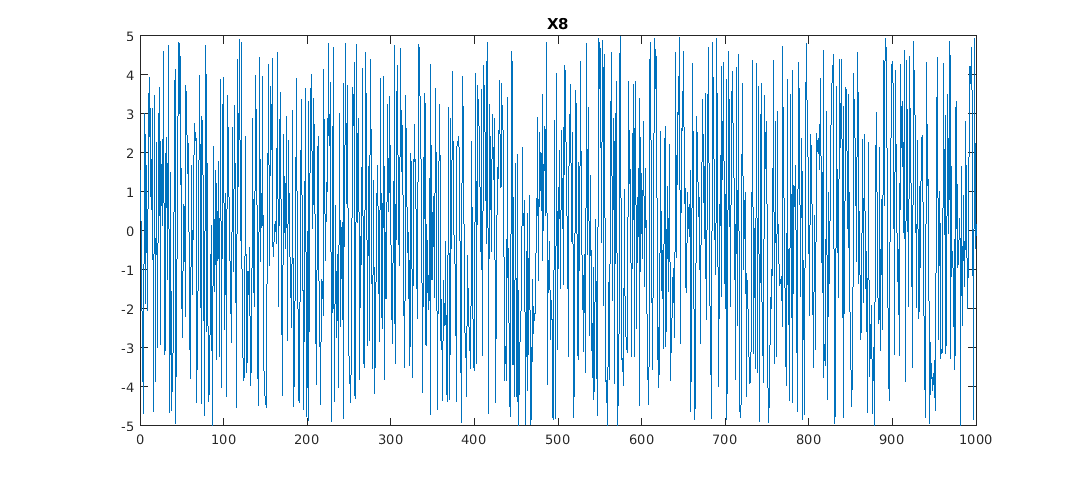

X8 = -5 + (5+5)*rand(1, N);
graph = figure;
plot(X8)
title('X8')
set(graph,'Units','normalized','Position',[0 0 1 0.25]);

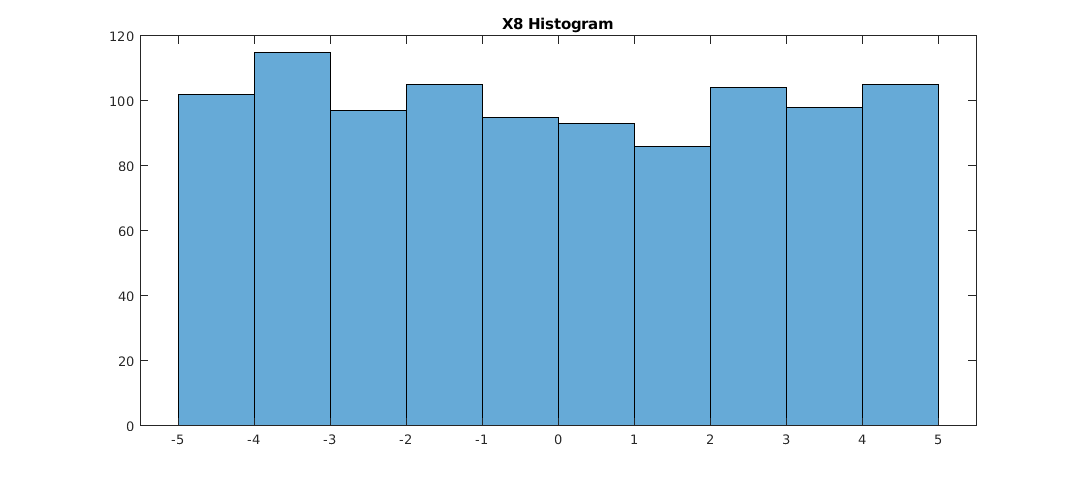

graph = figure;
histogram(X8)
title('X8 Histogram')
set(graph,'Units','normalized','Position',[0 0 1 0.25]); 

*Theoretical value of Mean and Variance for X8:*


$$\begin{array}{l}
A\;=-5\\
B\;=5\\
f\left(x\right)=\frac{1}{5-\left(-5\right)}=\frac{1}{10}
\end{array}$$



$$\mu = \mathrm{E}(X8) = \int_{-5}^{5} x\cdot(0
.1)\;dx$$



$$\mu ={0\ldotp 1\left\lbrack \frac{x^2 }{2}\right\rbrack }_{-5}^5 =0\ldotp 1\left(\frac{25}{2}-\frac{25}{2}\right)=0$$



$$\mathrm{var}(X8) =  \int_{-5}^{5} (x)^2 \cdot(0.1)\;dx$$



$$\sigma^2 =0\ldotp 1{\left\lbrack \frac{x^3 }{3}\right\rbrack }_{-5}^5 =0\ldotp 1\left(\frac{125}{3}-\frac{-125}{3}\right)\approx 8\ldotp 3333\;$$


% Theoretical Mean and Variance
mu8_theoretical = 0.0000;
var8_theoretical = 8.3333;

fprintf("Theoretical Mean of X8 = %f\n\nTheoretical Variance of X8 = %f"...
    , mu8_theoretical, var8_theoretical)

Theoretical Mean of X8 = 0.000000

Theoretical Variance of X8 = 8.333300

% MATLAB's Mean and Variance
mu8 = mean(X8);
var8 = var(X8);

fprintf("MATLAB's Mean of X8 = %f\n\nMATLAB's Variance of X8 = %f"...
    , mu8, var8);

MATLAB's Mean of X8 = -0.064423

MATLAB's Variance of X8 = 8.668097

% Percent Difference between the results
if mu8_theoretical >= mu8
    mu8_difference = 100*(mu8_theoretical - mu8)/mu8_theoretical;
    var8_difference = 100*(var8_theoretical - var8)/var8_theoretical;
else
    mu8_difference = 100*(mu8 - mu8_theoretical)/mu8;
    var8_difference = 100*(var8 - var8_theoretical)/var8;
end

if abs(mu8_difference) == inf || abs(mu8_difference) == 100
    mu8_difference = abs(mu8_theoretical - mu8);
end
if abs(var8_difference) == inf || abs(var8_difference) == 100
    var8_difference = abs(var8_theoretical - var8);
end

fprintf("Difference between MATLAB's Mean and Theoretical Mean = %.2f\n\n" +...
    "Difference between MATLAB's Variance and Theoretical Variance = %.2f%%"...
    , abs(mu8_difference), abs(var8_difference));

Difference between MATLAB's Mean and Theoretical Mean = 0.06

Difference between MATLAB's Variance and Theoretical Variance = 4.02%

*You can see how we have a slight difference between the results when we calculate our statistics based on the PDF.*

*Recall: We showed before how MATLAB calculates these statistics of the generated random numbers by lookingat all the numbers. It shows that the calculated number from MATLAB shows the correct statistics of the generated data and it could differ from the theoretical values we calculated.*

### X9) containing integers 1,2, …,6 at equal probability

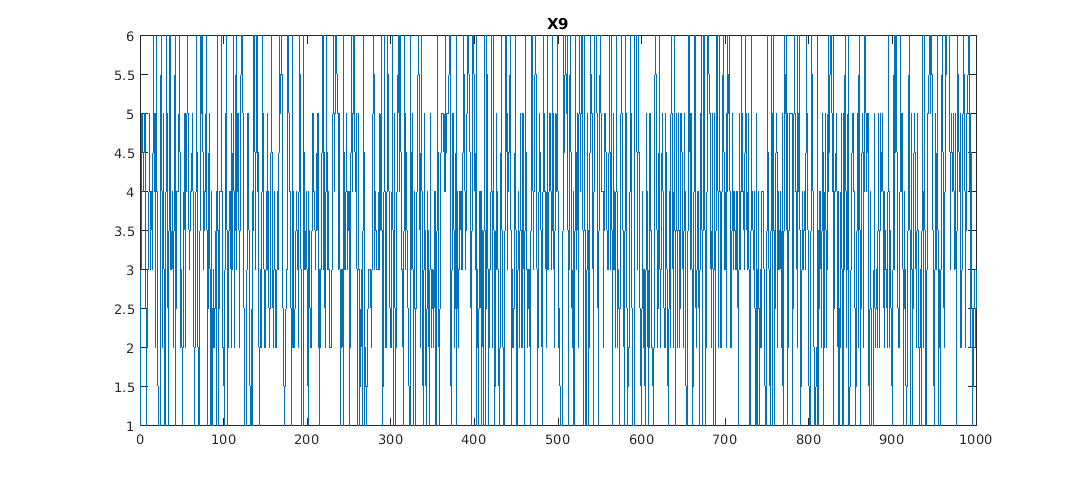

X9 = randi(6, 1, N);
graph = figure;
plot(X9)
title('X9')
set(graph,'Units','normalized','Position',[0 0 1 0.25]);

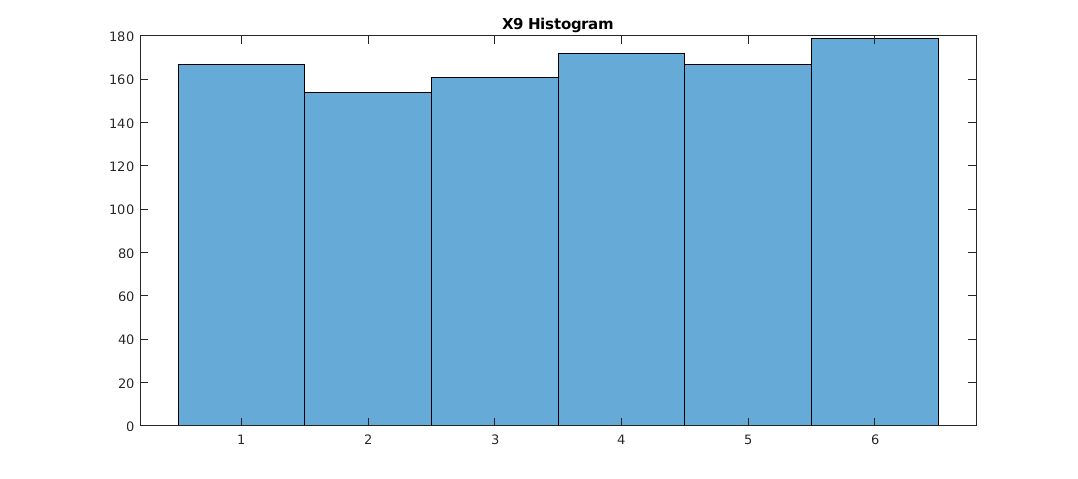

graph = figure;
histogram(X9)
title('X9 Histogram')
set(graph,'Units','normalized','Position',[0 0 1 0.25]); 

Mean of a Discrete random variable:


$$\mu = \mathrm{E}(X) = \sum x\,p(x),$$


Variance of a continuous random variable:


$$\mathrm{var}(X) = \sigma^2 = \mathrm{E}[(X - \mu)^2], \qquad\text{where } \mu = \mathrm{E}(X).$$



$$\mathrm{var}(X) = \sum (x - \mu)^2 p_X(x)$$


p(x) of Uniformly Disrtibuted random vectors:


$$p\left(x\right)=\frac{1}{m},\;x=1,2,3,\cdots ,m$$


*Theoretical value of Mean and Variance for X9:*


$$\mu(X9) = \sum_{x=1}^{m} \Bigl(x \times \frac{1}{m}\Bigr)$$



$$= \frac{1}{m}\, \sum_{x=1}^m x$$



$$= \frac{1}{m} \times \frac{m(m+1)}{2}$$



$$= \frac{m+1}{2}$$


*Here *$m=6$*, therefore;*


$$\mu = \frac{6 + 1}{2} = 3.5
$$



$$\mathrm{var}(X9) = \mathrm{E}[(X - \mu)^2]$$



$$= \sum (x - \mu)^2 p(x)$$



$$=\sum_{x=1}^m {\left(x-3\ldotp 5\right)}^2 \frac{1}{m}$$
 


$$=\frac{1}{m}\sum_{x=1}^m {\left(x-3\ldotp 5\right)}^2$$



$$=\frac{1}{m\;}\left(\sum_{x=1}^m x^2 -7\sum_{x=1}^m x+12\ldotp 25\sum_{x=1}^m 1\right)$$



$$=\frac{1}{m}\;\left(\left(\frac{1}{6}m\left(m+1\right)\left(2m+1\right)\right)-\left(\frac{7}{2}m\left(m+1\right)\right)+\left(12\ldotp 25m\right)\right)$$



$$=\;\frac{1}{m}\left(12\ldotp 25m+\frac{m\left(m+1\right)\left(m-10\right)}{3}\right)$$



$$=12\ldotp 25+\frac{\left(m+1\right)\left(m-10\right)}{3}$$


*Here *$m=6$*, therefore;*


$$\sigma^2 \;=12\ldotp 25+\frac{\left(6+1\right)\left(6-10\right)}{3}\approx 2\ldotp 91667$$


% Theoretical Mean and Variance
mu9_theoretical = 3.50000;
var9_theoretical = 2.91667;

fprintf("Theoretical Mean of X9 = %f\n\nTheoretical Variance of X9 = %f"...
    , mu9_theoretical, var9_theoretical)

Theoretical Mean of X9 = 3.500000

Theoretical Variance of X9 = 2.916670

% MATLAB's Mean and Variance
mu9 = mean(X9);
var9 = var(X9);

fprintf("MATLAB's Mean of X9 = %f\n\nMATLAB's Variance of X9 = %f"...
    , mu9, var9);

MATLAB's Mean of X9 = 3.555000

MATLAB's Variance of X9 = 2.967943

% Percent Difference between the results
if mu9_theoretical >= mu9
    mu9_difference = 100*(mu9_theoretical - mu9)/mu9_theoretical;
    var9_difference = 100*(var9_theoretical - var9)/var9_theoretical;
else
    mu9_difference = 100*(mu9 - mu9_theoretical)/mu9;
    var9_difference = 100*(var9 - var9_theoretical)/var9;
end

fprintf("Difference between MATLAB's Mean and Theoretical Mean = %.2f%%\n\n" +...
    "Difference between MATLAB's Variance and Theoretical Variance = %.2f%%"...
    , abs(mu9_difference), abs(var9_difference));

Difference between MATLAB's Mean and Theoretical Mean = 1.55%

Difference between MATLAB's Variance and Theoretical Variance = 1.73%

*You can see how we have a slight difference between the results when we calculate our statistics based on the PDF.*

*Recall: We showed before how MATLAB calculates these statistics of the generated random numbers by lookingat all the numbers. It shows that the calculated number from MATLAB shows the correct statistics of the generated data and it could differ from the theoretical values we calculated.*

### X10) containing integers 0,1 at equal probability

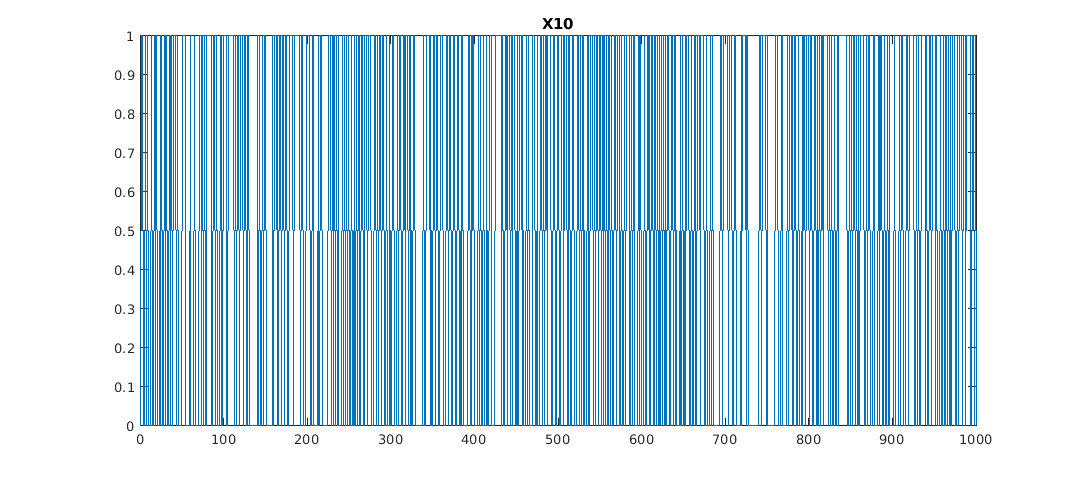

X10 = randi([0,1], 1, N);
graph = figure;
plot(X10)
title('X10')
set(graph,'Units','normalized','Position',[0 0 1 0.25]);

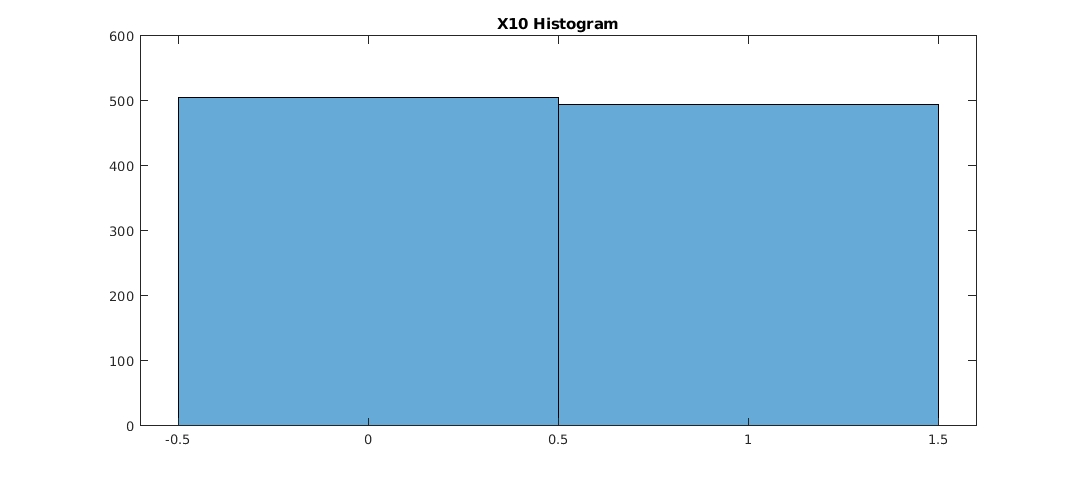

graph = figure;
histogram(X10)
title('X10 Histogram')
set(graph,'Units','normalized','Position',[0 0 1 0.25]); 

*Theoretical value of Mean and Variance for X10:*


$$p(x) = \frac{1}{2}$$



$$\mu \left(\textrm{X10}\right)=\sum_{x\;=\;0}^m x\cdot \frac{1}{2}$$



$$=\frac{1}{2}\left(a_0 +\sum_{x=1}^m x\right)$$



$$=\frac{1}{2}\;\left(0+\frac{1}{2}m\left(m+1\right)\right)$$



$$=\frac{1}{4}m\left(m+1\right)$$


*Here *$m=1$*, therefore;*


$$\mu =\frac{1}{4}\left(1\right)\left(2\right)=0\ldotp 5$$



$$\mathrm{var}(X10) = \mathrm{E}[(X - \mu)^2]$$



$$= \sum (x - \mu)^2 p(x)$$



$$=\sum_{x=0}^m {\left(x-0\ldotp 5\right)}^2 \frac{1}{2}$$
 


$$=\frac{1}{2}\left(a_0 +\sum_{x=1}^m {\left(x-0\ldotp 5\right)}^2 \right)$$



$$=\frac{1}{2\;}\left({\left(0-0\ldotp 5\right)}^2 +\sum_{x=1}^m x^2 -\sum_{x=1}^m x+0\ldotp 25\sum_{x=1}^m 1\right)$$



$$=\frac{1}{2}\;\left(0\ldotp 25+\left(\frac{1}{6}m\left(m+1\right)\left(2m+1\right)\right)-\left(\frac{1}{2}m\left(m+1\right)\right)+\left(0\ldotp 25m\right)\right)$$



$$=\;\frac{1}{2}\left(0\ldotp 25+0\ldotp 25m+\frac{m\left(m+1\right)\left(m-1\right)}{3}\right)$$


*Here *$m=1$*, therefore;*


$$\sigma^2 \;=\frac{1}{2}\left(0\ldotp 25+0\ldotp 25+\frac{1\left(1+1\right)\left(1-1\right)}{3}\right)=0\ldotp 25$$


% Theoretical Mean and Variance
mu10_theoretical = 0.500;
var10_theoretical = 0.250;

fprintf("Theoretical Mean of X10 = %f\n\nTheoretical Variance of X10 = %f"...
    , mu10_theoretical, var10_theoretical)

Theoretical Mean of X10 = 0.500000

Theoretical Variance of X10 = 0.250000

% MATLAB's Mean and Variance
mu10 = mean(X10);
var10 = var(X10);

fprintf("MATLAB's Mean of X10 = %f\n\nMATLAB's Variance of X10 = %f"...
    , mu10, var10);

MATLAB's Mean of X10 = 0.495000

MATLAB's Variance of X10 = 0.250225

% Percent Difference between the results
if mu10_theoretical >= mu10
    mu10_difference = 100*(mu10_theoretical - mu10)/mu10_theoretical;
    var10_difference = 100*(var10_theoretical - var10)/var10_theoretical;
else
    mu10_difference = 100*(mu10 - mu10_theoretical)/mu10;
    var10_difference = 100*(var10 - var10_theoretical)/var10;
end

fprintf("Difference between MATLAB's Mean and Theoretical Mean = %.2f%%\n\n" +...
    "Difference between MATLAB's Variance and Theoretical Variance = %.2f%%"...
    , abs(mu10_difference), abs(var10_difference));

Difference between MATLAB's Mean and Theoretical Mean = 1.00%

Difference between MATLAB's Variance and Theoretical Variance = 0.09%

*You can see how we have a slight difference between the results when we calculate our statistics based on the PDF.*

*Recall: We showed before how MATLAB calculates these statistics of the generated random numbers by lookingat all the numbers. It shows that the calculated number from MATLAB shows the correct statistics of the generated data and it could differ from the theoretical values we calculated.*

### X11) containing integers -1,1 at equal probability

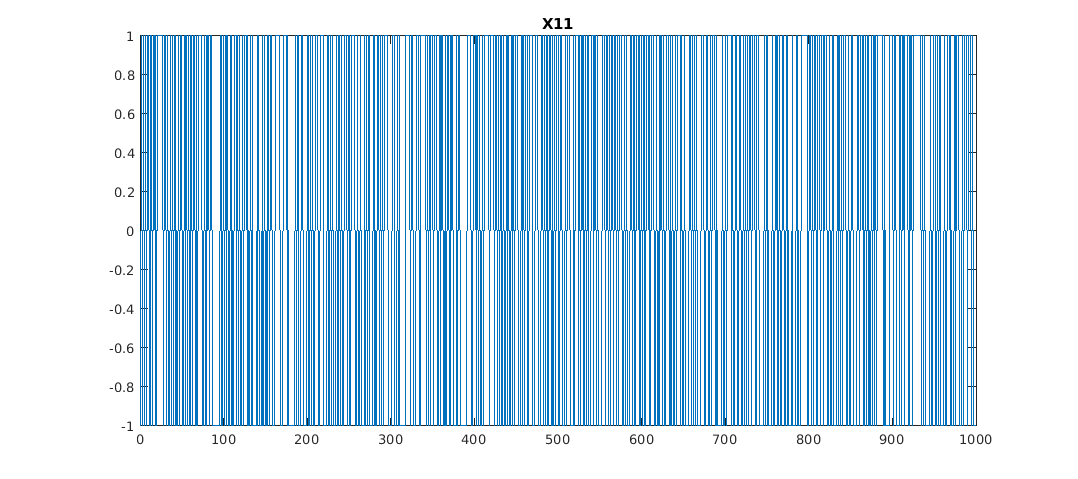

X11 = randi([0,1], 1, N);
X11(X11 == 0) = X11(X11 == 0) - 1;
graph = figure;
plot(X11)
title('X11')
set(graph,'Units','normalized','Position',[0 0 1 0.25]);

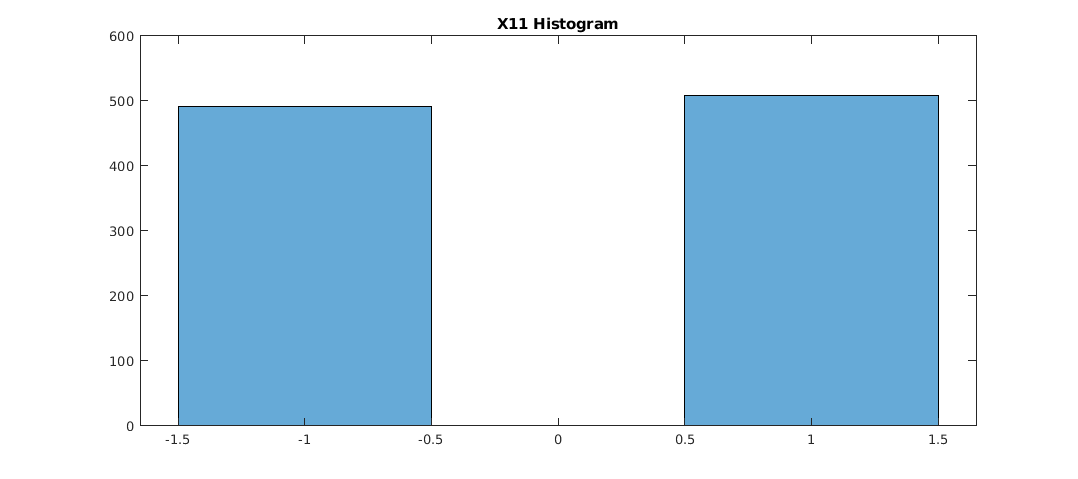

graph = figure;
histogram(X11)
title('X11 Histogram')
set(graph,'Units','normalized','Position',[0 0 1 0.25]); 

*Theoretical value of Mean and Variance for X11:*


$$p(x) = \frac{1}{2}$$



$$\mu \left(\textrm{X11}\right)=\sum_{x\;=-1}^m x\cdot \frac{1}{2}$$


*Reset Sum Index to start from 1*


$$=\;\sum_{k=1}^{m+2} \frac{1}{2}k-1$$



$$=\sum_{k=1}^{m+2} \frac{1}{2}k-\sum_{k=1}^{m+2} 1$$



$$=\;\frac{\left(m+2\right)\left(m+3\right)}{4}-\left(m+2\right)$$


*Here *$m=1$*, therefore:*


$$\mu \;=\frac{\left(1+2\right)\left(1+3\right)}{4}-\left(1+2\right)=0$$



$$\mathrm{var}(X11) = \mathrm{E}[(X - \mu)^2]$$



$$= \sum (x - \mu)^2 p(x)$$



$$=\sum_{x=-1}^m {\left(x\right)}^2 \frac{1}{2}$$
 


$$=\;$$

$$\sum_{k=1}^{m+2} {\left(k-2\right)}^2 \frac{1}{2}$$



$$=\frac{1}{2}\sum_{k=1}^{m+2} \left(k^2 -4k+4\right)$$



$$\vdots$$



$$=\frac{\left(m+2\right)\left(m+3\right)\left(2\left(m+2\right)+1\right)}{12}-\left(m+2\right)\left(m+3\right)+2\left(m+2\right)$$



$$=\frac{-12m^2 -36m+\left(m+2\right)\left(m+3\right)\left(2m+5\right)-24}{12}$$


*Here *$m=1$*, therefore:*


$$\sigma^2 =\frac{-12\left(1\right)-36\left(1\right)+\left(1+2\right)\left(1+3\right)\left(2\left(1\right)+5\right)-24}{12}=1$$


% Theoretical Mean and Variance
mu11_theoretical = 0.000;
var11_theoretical = 1.000;

fprintf("Theoretical Mean of X11 = %f\n\nTheoretical Variance of X11 = %f"...
    , mu11_theoretical, var11_theoretical)

Theoretical Mean of X11 = 0.000000

Theoretical Variance of X11 = 1.000000

% MATLAB's Mean and Variance
mu11 = mean(X11);
var11 = var(X11);

fprintf("MATLAB's Mean of X11 = %f\n\nMATLAB's Variance of X11 = %f"...
    , mu11, var10);

MATLAB's Mean of X11 = 0.018000

MATLAB's Variance of X11 = 0.250225

% Percent Difference between the results
if mu11_theoretical >= mu11
    mu11_difference = 100*(mu11_theoretical - mu11)/mu11_theoretical;
    var11_difference = 100*(var11_theoretical - var11)/var11_theoretical;
else
    mu11_difference = 100*(mu11 - mu11_theoretical)/mu11;
    var11_difference = 100*(var11 - var11_theoretical)/var11;
end

if abs(mu11_difference) == inf || abs(mu11_difference) == 100
    mu11_difference = abs(mu11_theoretical - mu11);
end
if abs(var11_difference) == inf || abs(var11_difference) == 100
    var11_difference = abs(var11_theoretical - var11);
end

fprintf("Difference between MATLAB's Mean and Theoretical Mean = %.2f\n\n" +...
    "Difference between MATLAB's Variance and Theoretical Variance = %.2f%%"...
    , abs(mu11_difference), abs(var11_difference));

Difference between MATLAB's Mean and Theoretical Mean = 0.02

Difference between MATLAB's Variance and Theoretical Variance = 0.07%

*You can see how we have a slight difference between the results when we calculate our statistics based on the PDF.*

*Recall: We showed before how MATLAB calculates these statistics of the generated random numbers by lookingat all the numbers. It shows that the calculated number from MATLAB shows the correct statistics of the generated data and it could differ from the theoretical values we calculated.*

## Problem 2) 

The attached MATLAB functions my_rand_process1(N) to my_rand_process5(N) each create a single realization of random processes X1 to X5. The objective of this assignment is to determine whether these processes are wide sense stationary (WSS). Use N=1000 in this assignment. Do NOT use MATLAB’s function xcorr() in this assignment.

### my_rand_process1

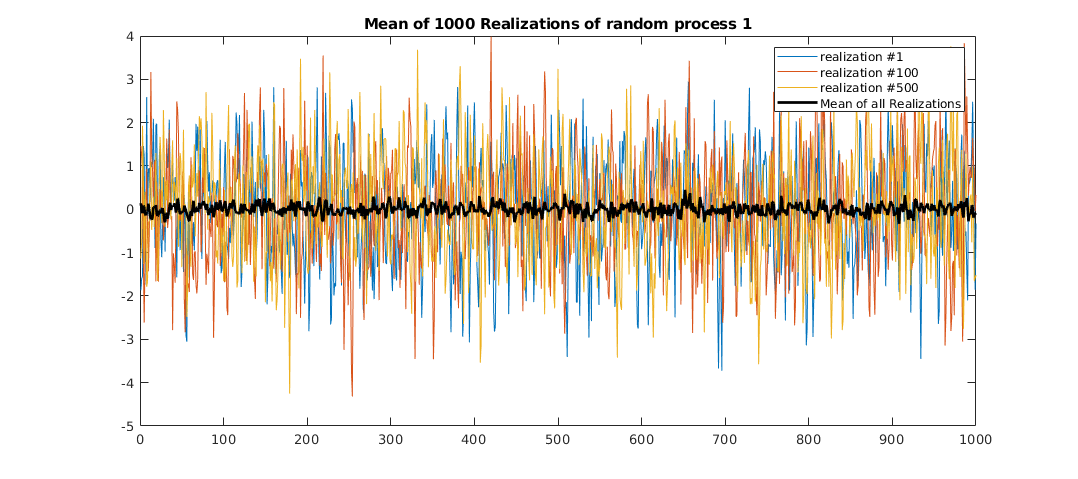

% We are going to make 1000 Realizations for this random process
N = 1000;
num_of_realizations = 100;

realizations1 = zeros(N , num_of_realizations);
for i= 1:num_of_realizations
    realizations1(:,i) = my_rand_process1(N);
end

mean_realizations1 = mean(realizations1, 2);
graph = figure;
plot(realizations1(:,1))
hold on
plot(realizations1(:,100))
plot(realizations1(:,50))
plot(mean_realizations1, 'k' , 'LineWidth', 2)
hold off
legend('realization #1', 'realization #100', 'realization #500', 'Mean of all Realizations')
title('Mean of 1000 Realizations of random process 1')
set(graph,'Units','normalized','Position',[0 0 1 0.25]);

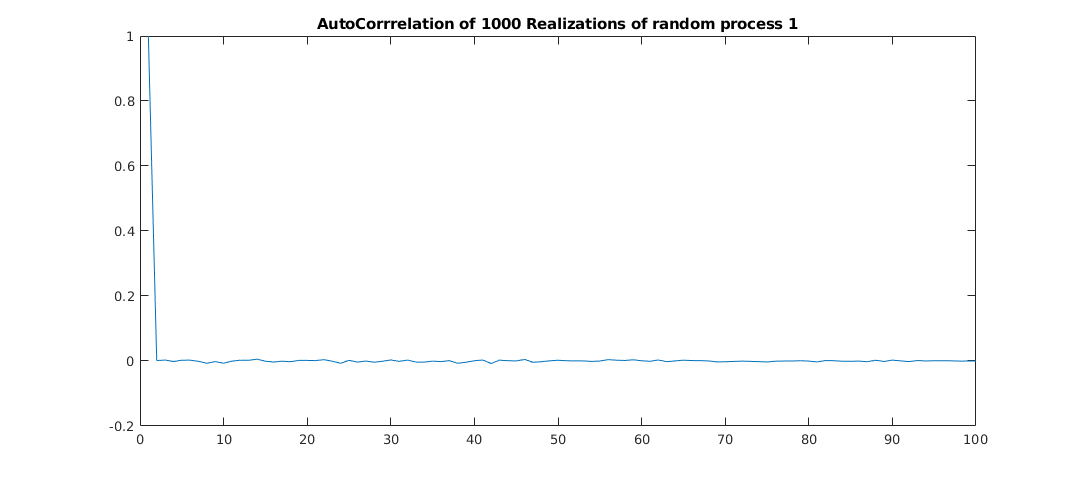

ACF = zeros(num_of_realizations,1);

muHat = mean(mean_realizations1); % sample mean

for iLag = 0:(num_of_realizations-1)
    index = 1;
    nPairs = (num_of_realizations-iLag)*N;
    pairs = zeros(nPairs,2);
    for iSample = 1:N
        for ix = 1:(num_of_realizations-iLag)
            pairs(index,1) = realizations1(iSample,ix);
            pairs(index,2) = realizations1(iSample,ix+iLag);
            index = index + 1;
        end
    end

    X2 = pairs(:,1)-muHat;
    Y2 = pairs(:,2)-muHat;
    ACF(iLag+1) = sum(X2.*Y2)/num_of_realizations*N; % calculate covariance
end
ACF = ACF/ACF(1); % divide by variance

graph = figure;
plot(ACF)
title('AutoCorrrelation of 1000 Realizations of random process 1')
set(graph,'Units','normalized','Position',[0 0 1 0.25]);

### my_rand_process2

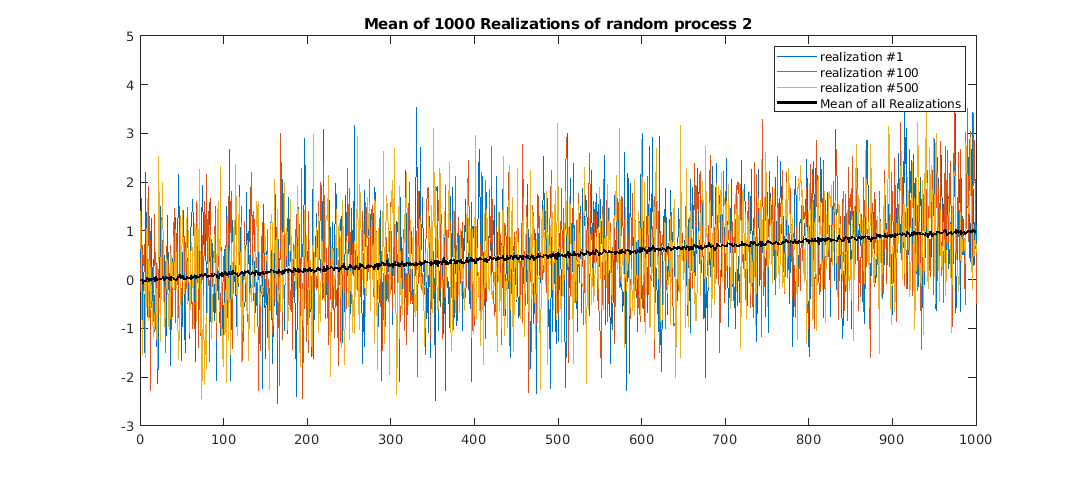

% We are going to make 1000 Realizations for this random process
realizations2 = zeros(N , num_of_realizations);
for i= 1:num_of_realizations
    realizations2(:,i) = my_rand_process2(N);
end

mean_realizations2 = mean(realizations2, 2);
graph = figure;
plot(realizations2(:,1))
hold on
plot(realizations2(:,100))
plot(realizations2(:,500))
plot(mean_realizations2, 'k' , 'LineWidth', 2)
hold off
legend('realization #1', 'realization #100', 'realization #500', 'Mean of all Realizations')
title('Mean of 1000 Realizations of random process 2')
set(graph,'Units','normalized','Position',[0 0 1 0.25]);

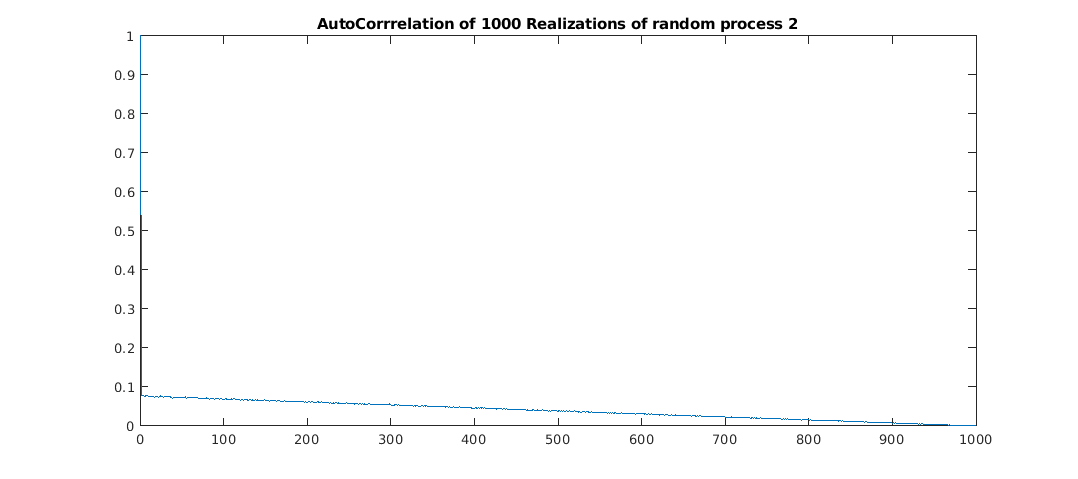

ACF2 = zeros(num_of_realizations,1);

muHat = mean(mean_realizations2); % sample mean

for iLag = 0:(num_of_realizations-1)
    index = 1;
    nPairs = (num_of_realizations-iLag)*N;
    pairs = zeros(nPairs,2);
    for iSample = 1:N
        for ix = 1:(num_of_realizations-iLag)
            pairs(index,1) = realizations2(iSample,ix);
            pairs(index,2) = realizations2(iSample,ix+iLag);
            index = index + 1;
        end
    end

    X2 = pairs(:,1)-muHat;
    Y2 = pairs(:,2)-muHat;
    ACF2(iLag+1) = sum(X2.*Y2)/num_of_realizations*N; % calculate covariance
end
ACF2 = ACF2/ACF2(1); % divide by variance

graph = figure;
plot(ACF2)
title('AutoCorrrelation of 1000 Realizations of random process 2')
set(graph,'Units','normalized','Position',[0 0 1 0.25]);

### my_rand_process3

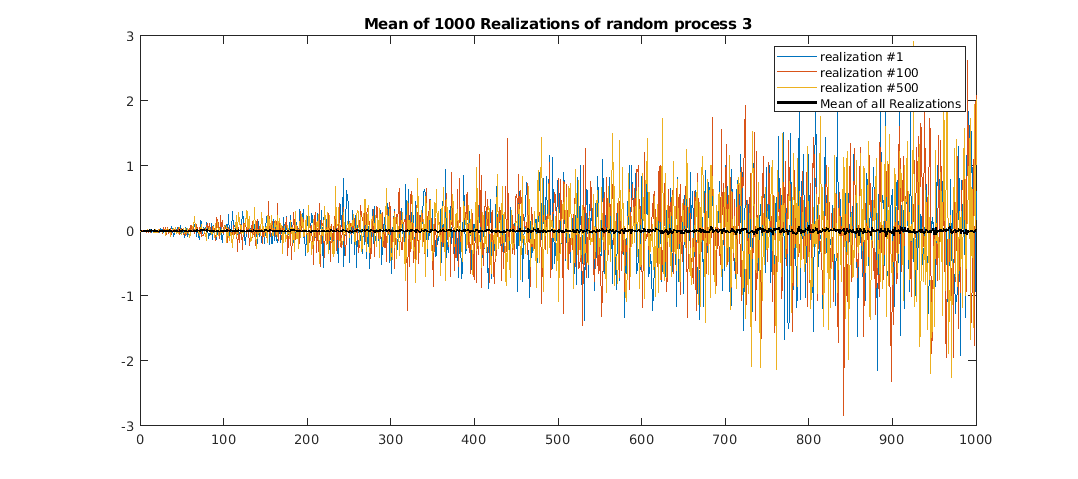

% We are going to make 1000 Realizations for this random process
realizations3 = zeros(N , num_of_realizations);
for i= 1:num_of_realizations
    realizations3(:,i) = my_rand_process3(N);
end

mean_realizations3 = mean(realizations3, 2);
graph = figure;
plot(realizations3(:,1))
hold on
plot(realizations3(:,100))
plot(realizations3(:,500))
plot(mean_realizations3, 'k' , 'LineWidth', 2)
hold off
legend('realization #1', 'realization #100', 'realization #500', 'Mean of all Realizations')
title('Mean of 1000 Realizations of random process 3')
set(graph,'Units','normalized','Position',[0 0 1 0.25]);

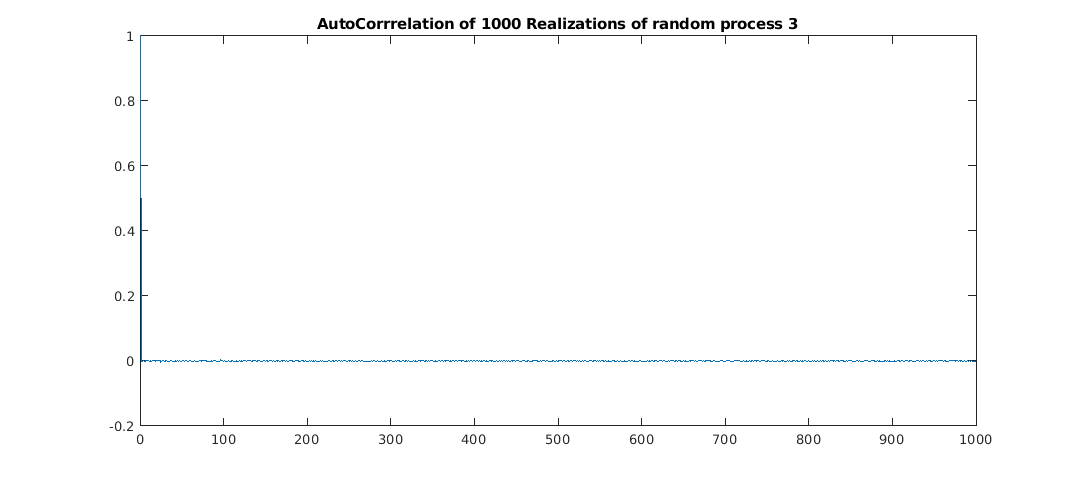

ACF3 = zeros(num_of_realizations,1);

muHat = mean(mean_realizations3); % sample mean

for iLag = 0:(num_of_realizations-1)
    index = 1;
    nPairs = (num_of_realizations-iLag)*N;
    pairs = zeros(nPairs,2);
    for iSample = 1:N
        for ix = 1:(num_of_realizations-iLag)
            pairs(index,1) = realizations3(iSample,ix);
            pairs(index,2) = realizations3(iSample,ix+iLag);
            index = index + 1;
        end
    end

    X2 = pairs(:,1)-muHat;
    Y2 = pairs(:,2)-muHat;
    ACF3(iLag+1) = sum(X2.*Y2)/num_of_realizations*N; % calculate covariance
end
ACF3 = ACF3/ACF3(1); % divide by variance

graph = figure;
plot(ACF3)
title('AutoCorrrelation of 1000 Realizations of random process 3')
set(graph,'Units','normalized','Position',[0 0 1 0.25]);

### my_rand_process4

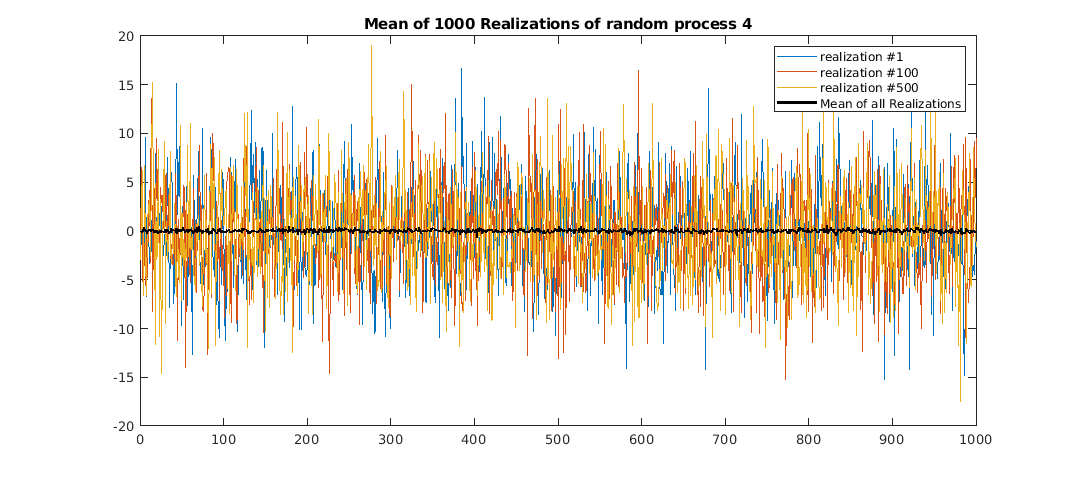

% We are going to make 1000 Realizations for this random process
realizations4 = zeros(N , num_of_realizations);
for i= 1:num_of_realizations
    realizations4(:,i) = my_rand_process4(N);
end

mean_realizations4 = mean(realizations4, 2);
graph = figure;
plot(realizations4(:,1))
hold on
plot(realizations4(:,100))
plot(realizations4(:,500))
plot(mean_realizations4, 'k' , 'LineWidth', 2)
hold off
legend('realization #1', 'realization #100', 'realization #500', 'Mean of all Realizations')
title('Mean of 1000 Realizations of random process 4')
set(graph,'Units','normalized','Position',[0 0 1 0.25]);

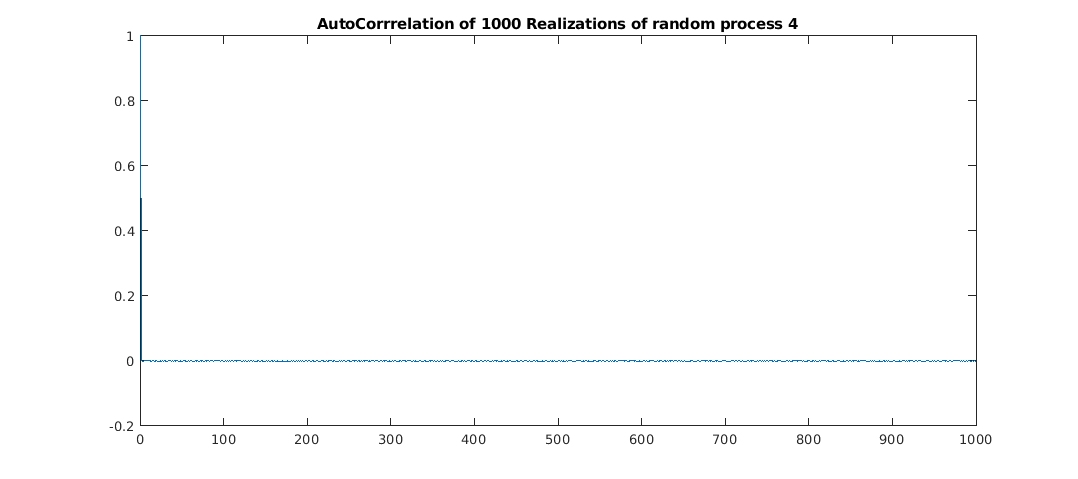

ACF4 = zeros(num_of_realizations,1);

muHat = mean(mean_realizations4); % sample mean

for iLag = 0:(num_of_realizations-1)
    index = 1;
    nPairs = (num_of_realizations-iLag)*N;
    pairs = zeros(nPairs,2);
    for iSample = 1:N
        for ix = 1:(num_of_realizations-iLag)
            pairs(index,1) = realizations4(iSample,ix);
            pairs(index,2) = realizations4(iSample,ix+iLag);
            index = index + 1;
        end
    end

    X2 = pairs(:,1)-muHat;
    Y2 = pairs(:,2)-muHat;
    ACF4(iLag+1) = sum(X2.*Y2)/num_of_realizations*N; % calculate covariance
end
ACF4 = ACF4/ACF4(1); % divide by variance

graph = figure;
plot(ACF4)
title('AutoCorrrelation of 1000 Realizations of random process 4')
set(graph,'Units','normalized','Position',[0 0 1 0.25]);

### my_rand_process5

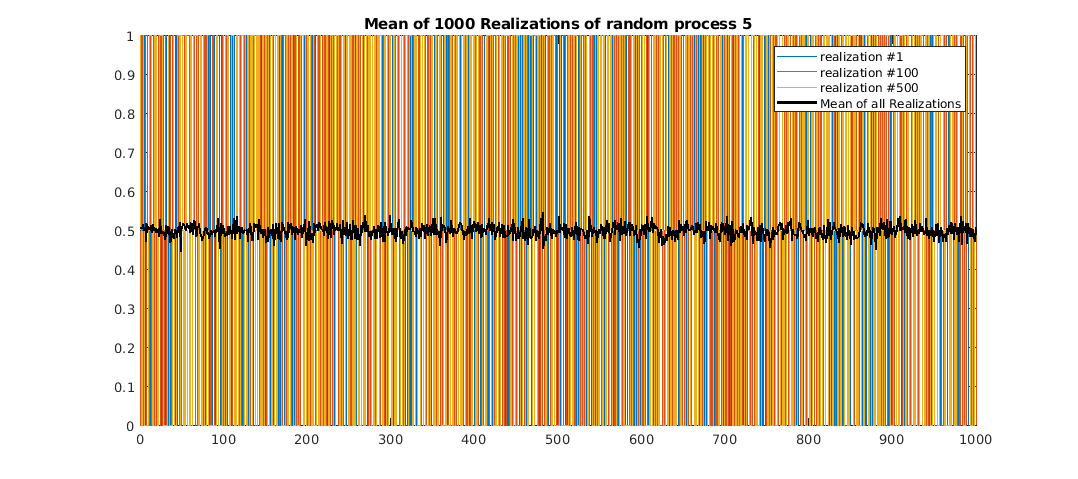

% We are going to make 1000 Realizations for this random process
realizations5 = zeros(N , num_of_realizations);
for i= 1:num_of_realizations
    realizations5(:,i) = my_rand_process5(N);
end

mean_realizations5 = mean(realizations5, 2);
graph = figure;
plot(realizations5(:,1))
hold on
plot(realizations5(:,100))
plot(realizations5(:,500))
plot(mean_realizations5, 'k' , 'LineWidth', 2)
hold off
legend('realization #1', 'realization #100', 'realization #500', 'Mean of all Realizations')
title('Mean of 1000 Realizations of random process 5')
set(graph,'Units','normalized','Position',[0 0 1 0.25]);

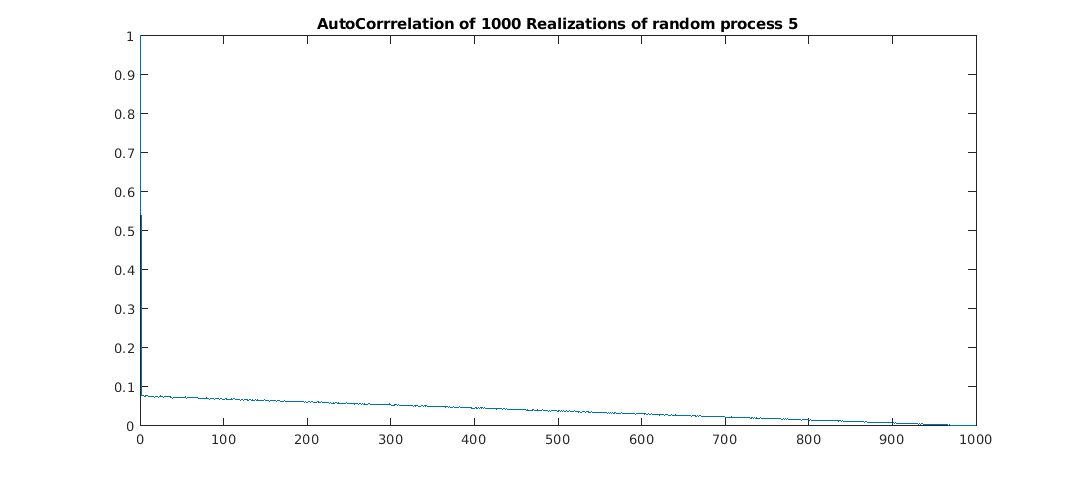

ACF5 = zeros(num_of_realizations,1);

muHat = mean(mean_realizations5); % sample mean

for iLag = 0:(num_of_realizations-1)
    index = 1;
    nPairs = (num_of_realizations-iLag)*N;
    pairs = zeros(nPairs,2);
    for iSample = 1:N
        for ix = 1:(num_of_realizations-iLag)
            pairs(index,1) = realizations2(iSample,ix);
            pairs(index,2) = realizations2(iSample,ix+iLag);
            index = index + 1;
        end
    end

    X2 = pairs(:,1)-muHat;
    Y2 = pairs(:,2)-muHat;
    ACF5(iLag+1) = sum(X2.*Y2)/num_of_realizations*N; % calculate covariance
end
ACF5 = ACF5/ACF5(1); % divide by variance

graph = figure;
plot(ACF5)
title('AutoCorrrelation of 1000 Realizations of random process 5')
set(graph,'Units','normalized','Position',[0 0 1 0.25]);